This file sets the parameters for all the blocks and variables used in the simulation model.

**Renewable plant parameters**

SimulationTime = 4;
BatteryStoragePVPlantGFMParameters;% PV and Battery plant parameters
offshoreWind;% Wind plant parameters
windTurbine.turbineRadius=120; % Turbine radius in meters

**Configure Wind Turbine MPPT parameters**

if false % Tick this block to generate the wind turbine characteristics by changing the turbine parameters
    windTurbine.turbineRadius=100; %#ok<*UNRCH> % Turbine radius in meters
    sweepTurbine;
    plotPowerCurves;
    mpptPower=maxPower*0.98;
    mpptWindSpeed=windSpeedv;
    mpptOmega=maxPowerRPM;
    windTurbine.turbineRatedPower=max(mpptPower);
end

Use the already generated turbine characteristics with turbine radius of 120 meters

if true % Tick this block to use the already generated turbine characteristics
load mpptPower.mat 
load power2.mat 
load mpptOmega.mat 
load mpptWindSpeed.mat
turbineRPMv = 1:20;
windTurbine.turbineRatedPower=max(mpptPower);
end

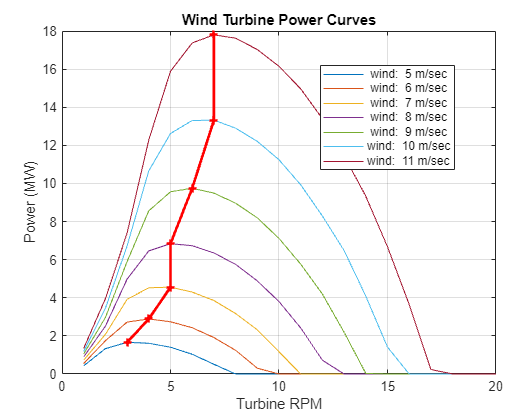

This figure shows the power vs speed characteristics of the wind turbine with radius of 120 meters.

**Parameters of HVDC Stations**

HVDC.L=3.1e-5;
HVDC.C=0.0095;
HVDC.Vdc=400e3;
HVDC.Vdcbase=1000e3;
HVDC.Imaxpu=1.2;
windTransformer.hv1=HVDC.Vdc/(1.2*sqrt(2));
windInverter.imaxPU=1.1;
base.kV1=windTransformer.hv1;
base.kV=4.16e3;
Base.MVA_base_new=1000e6;
Base.z_base=Base.KV_base_new^2/Base.MVA_base_new;
grid.sensorTime=2*Ts;

**Onshore GFM Controller Parameters**

%% GFM using Dc link voltage control 
onshoreGfm.damping=100;
onshoreGfm.inertiaconstant=0.5;
onshoreGfm.Pref=0.1;
onshoreGfm.Evfdroop=0.002;
onshoreGfm.QvVdroop=0.01;
onshoreGfm.Vref=1.01;
onshoreGfm.Imax=1.02;
%Voltage Controller Parameter
onshoreGfm.Kvp=1.5; %proportional gain
onshoreGfm.Kvi=0.1;
%Current Controller Parameter
onshoreGfm.Kip=1.5; %proportional gain
onshoreGfm.Kii=1000; %integral gain

**Onshore GFL Controller Parameters**

onshoreGfl.vdckpv=1;
onshoreGfl.vdckiv=1000;
onshoreGfl.ikp=2.04;
onshoreGfl.iki=500;
onshoreGfl.ikd=0.5;

**Offshore GFM Controller Parameters**

offshoregfm.kvp=1; %proportional gain
offshoregfm.kvi=0.1; %integral gain
offshoregfm.kii=300; %integral gain
offshoregfm.kip=1; %proportional gain
offshoregfm.Imax=1.2; % Max current in pu

**Grid Parameters**

grid.governor_droop=5e-4;
grid.H=1;
grid.MVA=100e6;
grid.Pref=0.01;
grid.damping=0.02;
if true % For weak grid
grid.ls=2.97e-2; % inductance in H
grid.rs=0.1; % resistance in ohms
end
if false % For strong grid 
grid.ls=1.97e-2; % inductance in H
grid.rs=0.1; % resistance in ohms
end

line.length=20; % Line resistance (km)
line.r=0.01; % Line resistance (Ohm/km)
line.l=2.6; % Line resistance (mH/km)
line.c=0.1; % Line resistance (micro Farad/km)
line.lm=0.1; % Line resistance (mH/km)
line.cl=0.03; % Line resistance (micro Farad/km)

**Parameter for event generation**

time.renewablevariation=11;
time.fault=11;
time.load=11;
time.island=11;
time.dcfault=11;
Tsim=4; %#ok<NASGU>

**Frequency Scan Parameters**

scan.end=6;% time to end frequency scan
scan.start=2;% time to start frequency scan
scan.samplingfrequency=5e3;% Sampling frequency of frequency scan
scan.Vd=0.01;% Disturbance voltage magnitude in PU
scan.Vq=0.0;% Disturbance voltage magnitude in PU
scan.Vdc=0.0; % Disturbance voltage magnitude in PU
scan.Vd1=0.0;% Disturbance voltage magnitude in PU
scan.Vq1=0.0;% Disturbance voltage magnitude in PU
scan.Vdc1=0.0; % Disturbance voltage magnitude in PU
scan.f=(1:1e4)/(2*pi); % Range of disturbance frequency in Hz
modelorder=4; % Model order to obtain a reduced ordered admittance model of the system
Tsim=scan.end+0.2;